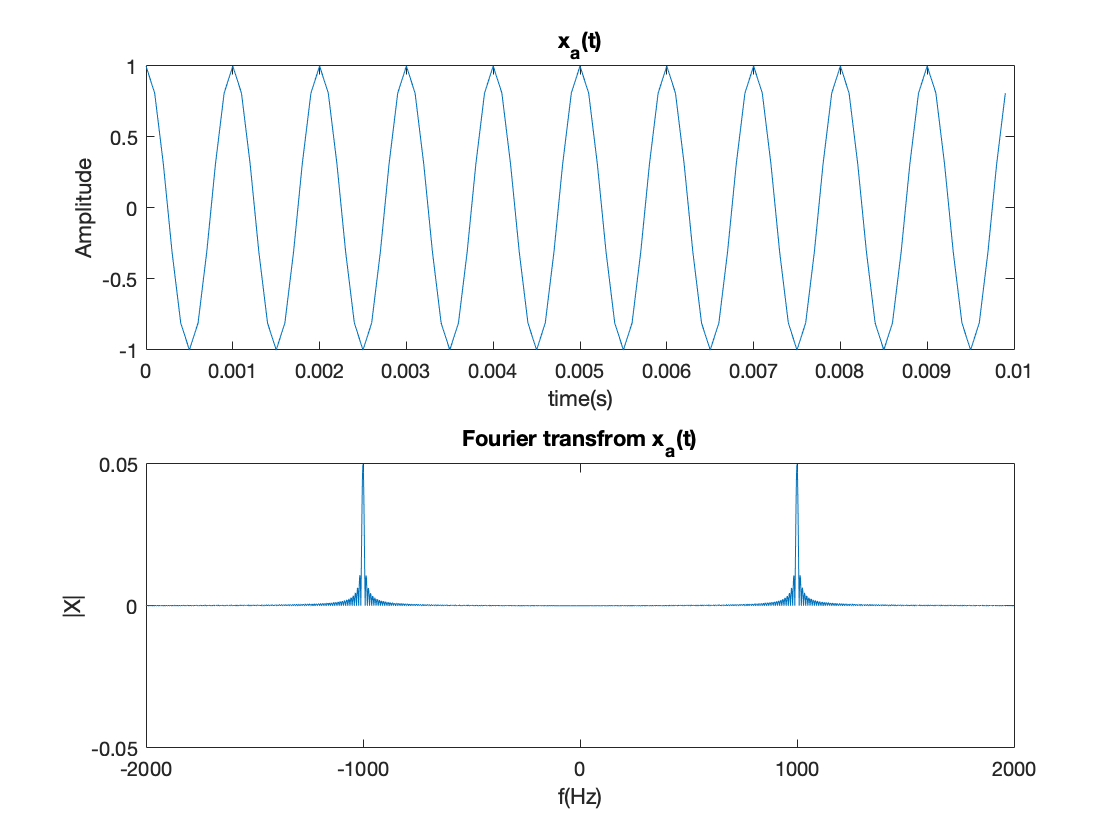

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : Continous Fourier transform 
%----------------------------------------------------------------------
close all;
clc;

%x_a(t) = cos(2000*pi*t) - it is approximated as discrete 
%by chossing decimated time points
Fs = 10000;
T = 1/Fs;
L = 1000; %no of samples 
t = [0:L-1]*T;

%given signal
x_a = cos(2000*pi*t);

subplot(2,1,1);
plot(t(1:100),x_a(1:100));
xlabel('time(s)');
ylabel('Amplitude')
title('x_a(t)')
hold on
%computing fourier transform 
%approximating signal as bandlimited from f = -2000 to 2000 Hz
X = zeros(1, 4001);

k = 0;
for f = -2000:1:2000
    k = k+1;
    X(k) = trapz(t, x_a.*exp(-1j*2*pi*f*t)); %trapz = computes integration using trapezoidal approximation
end

subplot(2,1,2);
plot(-2000:2000, abs(X));
axis([-2000 2000 -.05 0.05]);
xticks([-2000, -1000, 0, 1000, 2000]);
xlabel('f(Hz)');
ylabel('|X|');
title('Fourier transfrom x_a(t)')